# 探索的データ分析(EDA)を行う

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

シーズンごとにチーム数，地区数，および試合数を集計する．試合数はレギュラーシーズンとプレイオフを分けて集計する．

シーズンの判定には数値であるSeasonStartYearが扱いやすい．

seasonStartYearVals=unique(tbl_teams.SeasonStartYear);
plotData=[];    %図示用データ
for seasonStartYearVal=seasonStartYearVals'
    ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
    tbl_teams_tmp=tbl_teams(ind,:);
    numTeams=size(unique(tbl_teams_tmp.TeamName),1);
    numDivisions=size(unique(tbl_teams_tmp.Division),1);

    ind = tbl_results.SeasonStartYear==seasonStartYearVal;
    tbl_results_tmp=tbl_results(ind,:);
    numRegularMatches=sum(tbl_results_tmp.isRegular,1);
    numPlayoffMatches=sum(tbl_results_tmp.isPlayoff,1);

    plotData=[plotData; ...
        seasonStartYearVal numTeams numDivisions numRegularMatches numPlayoffMatches];
end

上下のグラフで図示する．

figure;

縦3個，横1個のグラフ領域(tile)を確保

tiledlayout(3,1);

次のtileを選択する

ax1=nexttile;
plot(plotData(:,1), plotData(:,2),'o-');
set(gca,'fontname','メイリオ');grid on;
ylabel('チーム数')
ax2=nexttile;
plot(plotData(:,1), plotData(:,3),'o-');
set(gca,'fontname','メイリオ');grid on;
ylabel('地区数');
ax3=nexttile;
bar(plotData(:,1), plotData(:,4:5),'stacked');
set(gca,'fontname','メイリオ');grid on;
ylabel('試合数');
xlabel('シーズン開始年');

3つのグラフでx軸を同期する

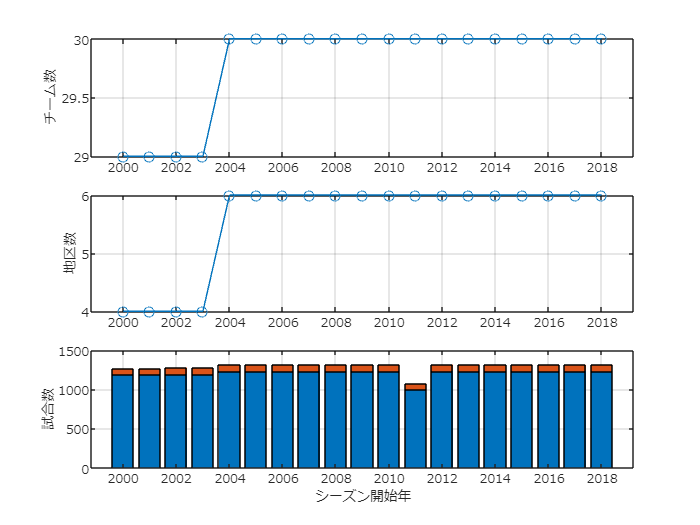

linkaxes([ax1;ax2;ax3],'x');
exportgraphics(gcf,'fig_NBANumOfTeamsAndDivisions.pdf')

シーズンの長さ(開幕から閉幕までの日数)

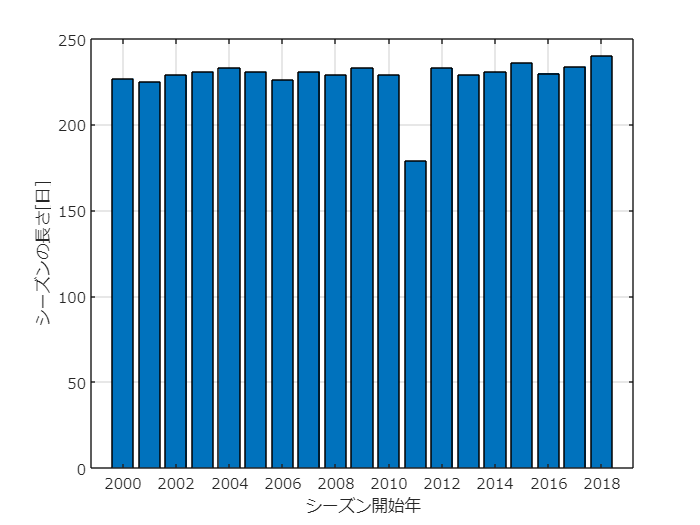

plotData=[];    %図示用データ
for seasonStartYearVal=seasonStartYearVals'
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;
    tbl_results_tmp=tbl_results(ind,:);
    daysOfOverallSeason=days(max(tbl_results_tmp.Date)-min(tbl_results_tmp.Date));

    plotData=[plotData; ...
        seasonStartYearVal daysOfOverallSeason];
end

figure;
bar(plotData(:,1), plotData(:,2));
ylabel('シーズンの長さ[日]');
xlabel('シーズン開始年');
set(gca,'fontname','メイリオ');grid on;
exportgraphics(gcf,'fig_NBADaysOfSeasons.pdf')

平均得点の推移

plotData=[];    %図示用データ
for seasonStartYearVal=seasonStartYearVals'
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;
    tbl_results_tmp=tbl_results(ind,:);
    plotData=[plotData; ...
        seasonStartYearVal ...
        mean([tbl_results_tmp.HomeScore;tbl_results_tmp.AwayScore]) ...
        mean(tbl_results_tmp.HomeScore) ...
        mean(tbl_results_tmp.AwayScore)];
end
figure;
plot(plotData(:,1),plotData(:,2:4));

データ列ごとに色・線の種類・マーカを変えるための設定

(色はデフォルトで変化するよう設定されている)

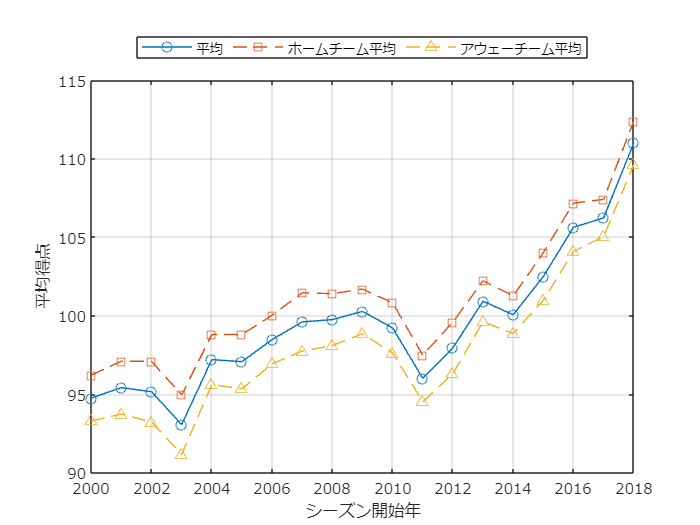

ax=gca;
mylinestyles = ["-o"; "--s"; "--^"];
ax.LineStyleOrder = mylinestyles;
ax.LineStyleCyclingMethod = "withcolor";
set(gca,'fontname','メイリオ');grid on;
ylabel('平均得点');
xlabel('シーズン開始年');
legend('平均','ホームチーム平均','アウェーチーム平均', ...
    'Location','northoutside','Orientation','horizontal');
exportgraphics(gcf,'fig_NBAMeanScore.pdf')

2011-12までの得点分布を度数分布(ヒストグラム)で描画する

figure;
ind = tbl_results.SeasonStartYear<=2011;
h1=histogram([tbl_results.HomeScore(ind);tbl_results.AwayScore(ind)]);
h1.EdgeColor='none';
set(gca,'fontname','メイリオ');grid on;

グラフの上書きを設定する

hold on;

2012-13以降の得点分布を追記する

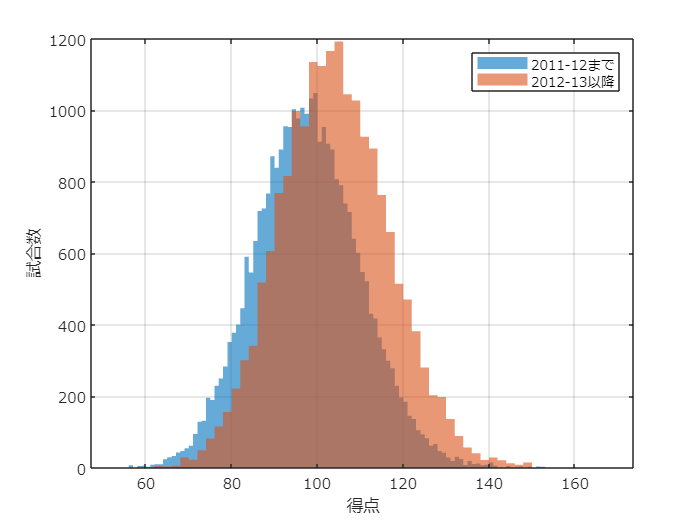

ind = tbl_results.SeasonStartYear>2011;
h2=histogram([tbl_results.HomeScore(ind);tbl_results.AwayScore(ind)]);
h2.EdgeColor='none';
xlabel('得点');
ylabel('試合数');
legend({'2011-12まで','2012-13以降'});
exportgraphics(gcf,'fig_NBAScoreHistogram.pdf');

シーズンごとに得点分布を図示する．

箱ひげ図(boxchart)を使う

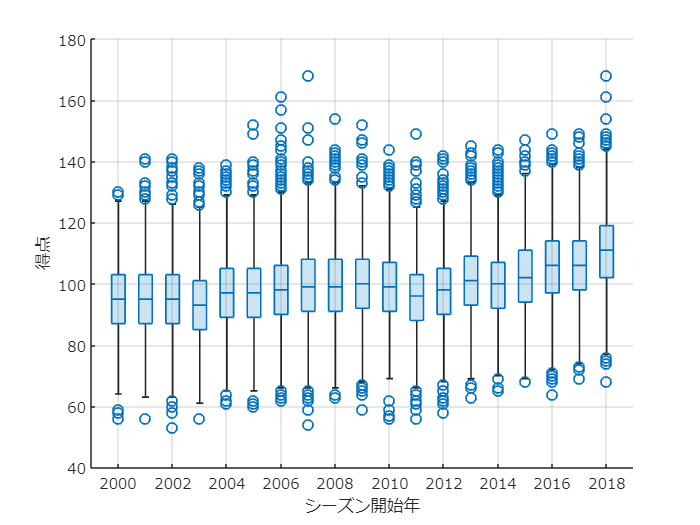

figure
boxchart([tbl_results.SeasonStartYear; ...
    tbl_results.SeasonStartYear] ...
    ,[tbl_results.HomeScore; ...
    tbl_results.AwayScore]);
set(gca,'fontname','メイリオ');grid on;
ylabel('得点');
xlabel('シーズン開始年');
xlim([min(seasonStartYearVals)-1, max(seasonStartYearVals)+1]);
exportgraphics(gcf,'fig_NBAScoreBoxchart.pdf');

最新シーズンについて対戦数を集計する

seasonStartYearVal=max(seasonStartYearVals)

seasonStartYearVal = 2018

ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);

レギュラーシーズンの試合のみ抽出する

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_tmp=tbl_results(ind,:);

チームをカンファレンス/ディビジョンでソート

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'Conference','Division'})

tbl_teams_tmp = 30×6 table
    SeasonStr    SeasonStartYear         TeamName          Conference    Division     Abb
    _________    _______________    ___________________    __________    _________    ___

    2018-2019         2018          Boston Celtics          Eastern      Atlantic     BOS
    2018-2019         2018          Brooklyn Nets           Eastern      Atlantic     BKN
    2018-2019         2018          New York Knicks         Eastern      Atlantic     NYK
    2018-2019         2018          Philadelphia 76ers      Eastern      Atlantic     PHI
    2018-2019         2018          Toronto Raptors         Eastern      Atlantic     TOR
    2018-2019         2018          Chicago Bulls           Eastern      Central      CHI
    2018-2019         2018          Cleveland Cavaliers     Eastern      Central      CLE
    2018-2019         2018          Detroit Pistons         Eastern      Central      DET
    2018-2019         2018          Indiana Pacers          Eastern     

試合数を集計する．(ホーム，アウェー)で試合数を格納する変数matchCountsを用意する

matchCounts=zeros(size(tbl_teams_tmp,1));
for n1=1:size(tbl_results_tmp,1)
    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_tmp.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_tmp.Away(n1));
    matchCounts(TeamANum, TeamBNum)=matchCounts(TeamANum, TeamBNum)+1;
end

imagesc関数で数値を色として表示する．

colorbar関数は色と数値の対応を示す棒を表示する関数(デフォルトでは右側)

figure
imagesc(matchCounts);colorbar;
set(gca,'fontname','メイリオ');
axis square;
xticks(1:size(tbl_teams_tmp,1));
yticks(1:size(tbl_teams_tmp,1));
xticklabels(tbl_teams_tmp.Abb);
yticklabels(tbl_teams_tmp.Abb);
ylabel('Home');
xlabel('Away');

Divisionが変化する場所に黒線を引く

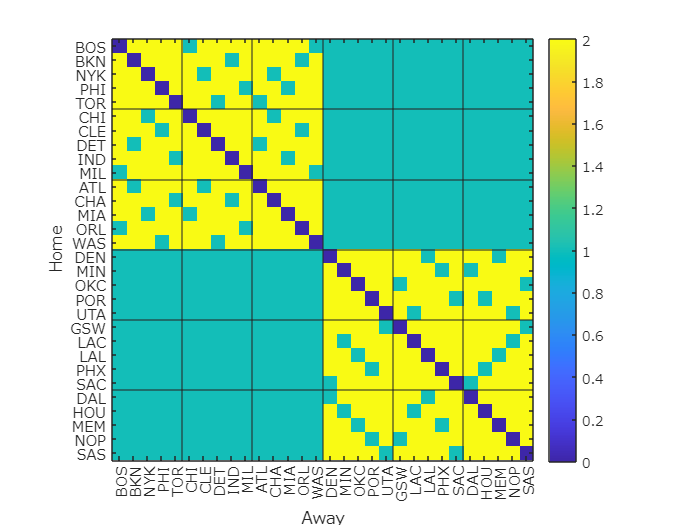

for n1=2:size(tbl_teams_tmp,1)-1
    if tbl_teams_tmp.Division(n1)~=tbl_teams_tmp.Division(n1-1)
        xline(n1-0.5);
        yline(n1-0.5);
    end
end
exportgraphics(gcf,'fig_NBAMatchCounts.pdf')